First, let's name the data series we'll be using


clear variables;

dataSeriesId = 1;
[shortname,fullname] = data_set_info(dataSeriesId);

data = get_small_data_set( shortname );

[shep_dim, red_dims] = data_set_misc_info( shortname );


Grab a couple of thousand random values from the data set into two separate collections...

witnessSize = 2000;
dataSize = 50;

randIds = getRandomIds(witnessSize + dataSize, size(data,1));

witnesses = data(randIds(1:witnessSize),:);
data = data(randIds(witnessSize + 1 : witnessSize + dataSize),:);

clear randIds;

Now we'll create the reduction transforms: pca, mds, nsimp zen, rp for first analysis, Shepard plots and Kruskal stress (displayed on plot)


%shepardReductionDimension has been set at the start depending on data set
%but can be overridden to show different typically smaller reductions...

[coeff,score,latent,tsquared,explained,mu] = pca( witnesses );

nsimpP = NsimpProjection(witnesses,shep_dim, @euc);
randP = RandomProjection(size(data,2),shep_dim);
mdsP = LmdsProjection(double(witnesses(1:max(500,shep_dim+1),:)), shep_dim, @euc);

pcaProj = data * coeff(:,1:shep_dim);

nsimpProj = zeros(dataSize,shep_dim);
randProj = zeros(dataSize,shep_dim);
mdsProj = zeros(dataSize,shep_dim);

for i = 1 : dataSize
    nsimpProj(i,:) = nsimpP.project(data(i,:));
    randProj(i,:) = randP.project(data(i,:));
    mdsProj(i,:) = mdsP.project(data(i,:));
end


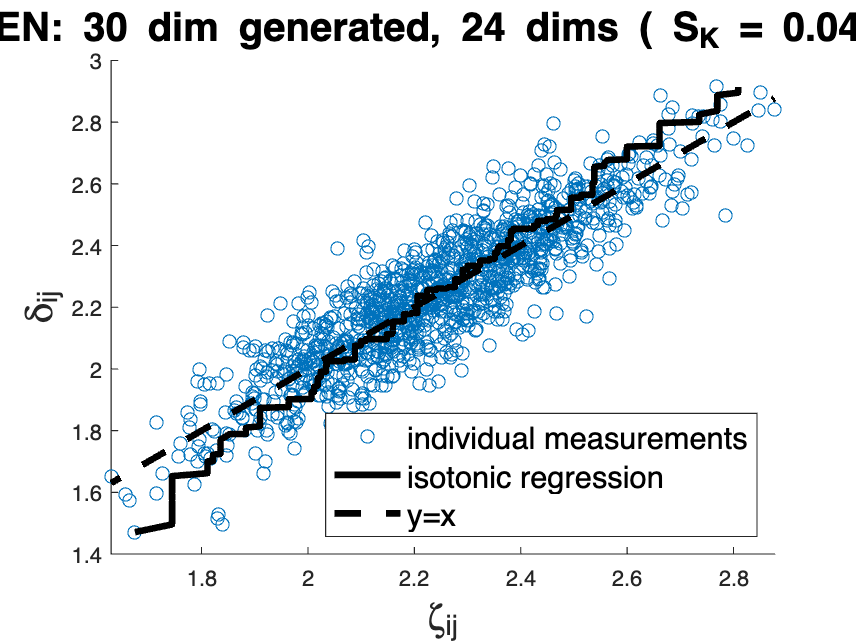


expTitle = strcat( fullname,", ", int2str(shep_dim)," dims");


shepard(pdist(data),pdist(nsimpProj,@zen),strcat("ZEN: ",expTitle));

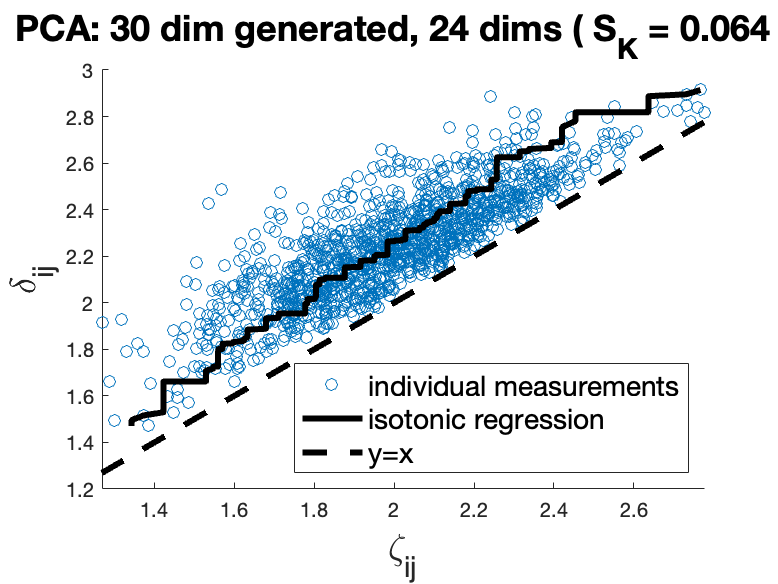

shepard(pdist(data),pdist(pcaProj),strcat("PCA: ",expTitle));

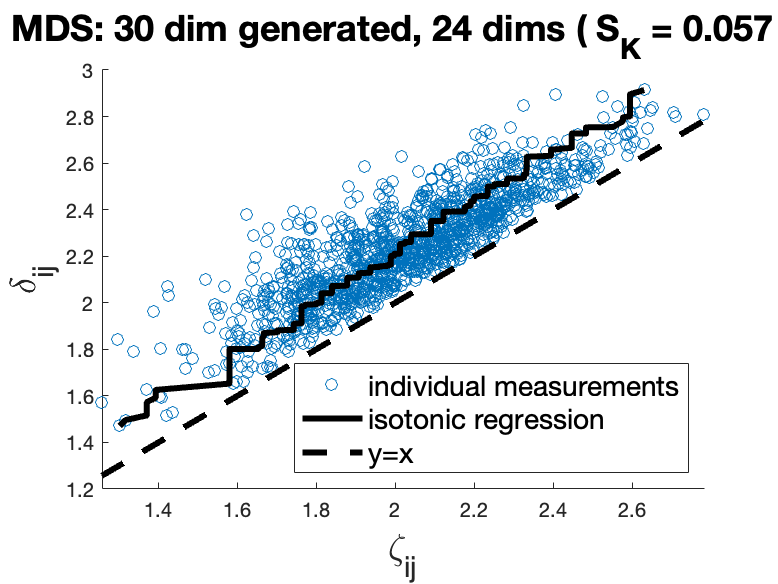

shepard(pdist(data),pdist(mdsProj),strcat("MDS: ", expTitle));

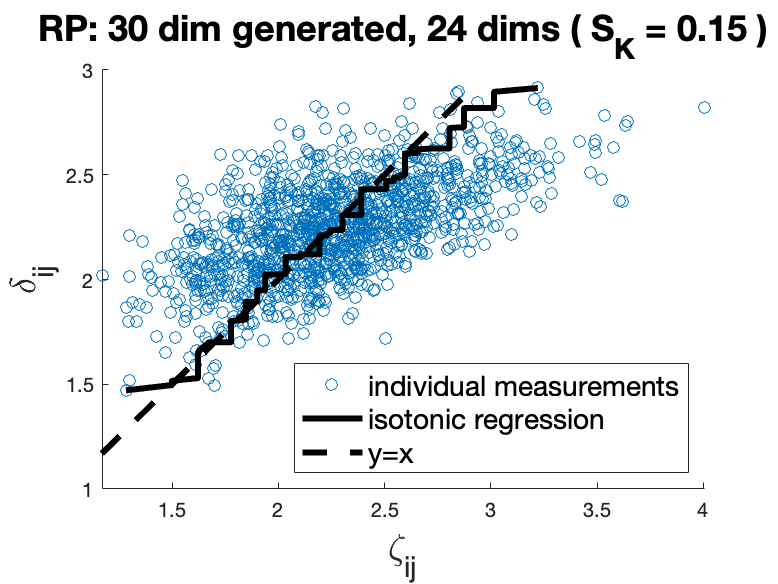

shepard(pdist(data),pdist(randProj),strcat("RP: ",expTitle));

% shepard(pdist(data),pdist(nsimpProj),strcat("LWB: ",expTitle));
% shepard(pdist(data),pdist(nsimpProj,@simpUpb),strcat("UPB: ", expTitle));
